# Computational Physics (PHY4602) - Graphics

## Overview

A picture, it is said, is worth a thousand words. MATLAB has a powerful graphics system for presenting and visualizing data and communicating results, which is reasonably easy to be customized either interactively or programmatically. Graphics functions include 2-D and 3-D plotting functions. Note that functions demonstrated here are non-exhaustive; MATLAB provides [more options](https://www.mathworks.com/help/matlab/examples.html?category=graphics&s_tid=CRUX_topnav) for users to visualize their data, which are continuously added and improved with future releases of the software.

## Basic Graphics

### 2-D Line Plot

The `plot` function creates a 2-D line plot of the data in `Y` versus the corresponding values in X. 

- To plot a set of coordinates connected by line segments, specify `X` and `Y` as vectors of the same length.

- To plot multiple sets of coordinates on the same set of axes, specify at least one of `X` or `Y` as a matrix.

The following code plots three sine curves with a small phase shift between each line. 

x = 0 : pi/10 : 2*pi;
y1 = sin(x);
y2 = sin(x - 0.25);
y3 = sin(x - 0.5);
plot(x, y1, 'g', x, y2, 'b--o', x, y3, 'c*')
xlabel('x'), ylabel('f(x)');
legend('sin(x)', 'sin(x - 0.25)', 'sin(x - 0.5)');
title('Phase shifted sine curves');

A green line with no markers was used for the first sine curve, a blue dashed line with circle markers for the second sine curve and only cyan star markers for the third sine curve.

Lines and markers can be customized even further by specifying more `LineSpec` in `plot(x, y, LineSpec)` options as follows:

x = -pi : pi/10 : pi;
y = tan(sin(x)) - sin(tan(x));
plot(x, y, '--gs', LineWidth = 2, MarkerSize = 10, MarkerEdgeColor = 'b', MarkerFaceColor = [0.5, 0.5, 0.5]);

### Histogram

Histograms are a type of bar plot for numeric data that group the data into bins. The code below plots a histogram of 1000 random numbers sorted into 25 equally spaced bins, where both values can be changed:

ExponentialFactor = 6;
NumData = 10^ExponentialFactor;
Data = randn(NumData, 1);
NumBins = 30;
histogram(Data, NumBins);
xlabel('Value'); ylabel('Count');

### Bar Graph

The function `bar(y)` creates a bar graph with one bar for each element in `y`.

- To plot a single series of bars, specify `y` as a vector of length *m*. The bars are positioned from `1` to *m* along the *x*-axis.

- To plot multiple series of bars, specify `y` as a matrix with one column for each series.

The following demonstrates plotting multiple series of bars with grouped (default) and stacked layout:

y = [2 2 3; 2 5 6; 2 8 9; 2 11 12];
BarsGrouped = bar(y);
title('Grouped bar graphs');
BarsStacked = bar(y, BarLayout = 'stacked');
title('Stacked bar graphs');

### Heatmap

A heatmap is a data visualization technique that shows magnitude of a phenomenon as color in two dimensions. The `heatmap(XLabel, YLabel, ColorData)` creates a heatmap based of `CData` and labels the values that appear along the *x*-axis and *y*-axis.

XLabels = ["A", "B", "C"];
YLabels = 1 : 4;
ColorData = [45 60 32; 43 54 76; 32 94 68; 23 95 58];
h = heatmap(XLabels, YLabels, ColorData);
colormap("bone");

### STEM Spotlight 💡: Fractal Pattern in Nature

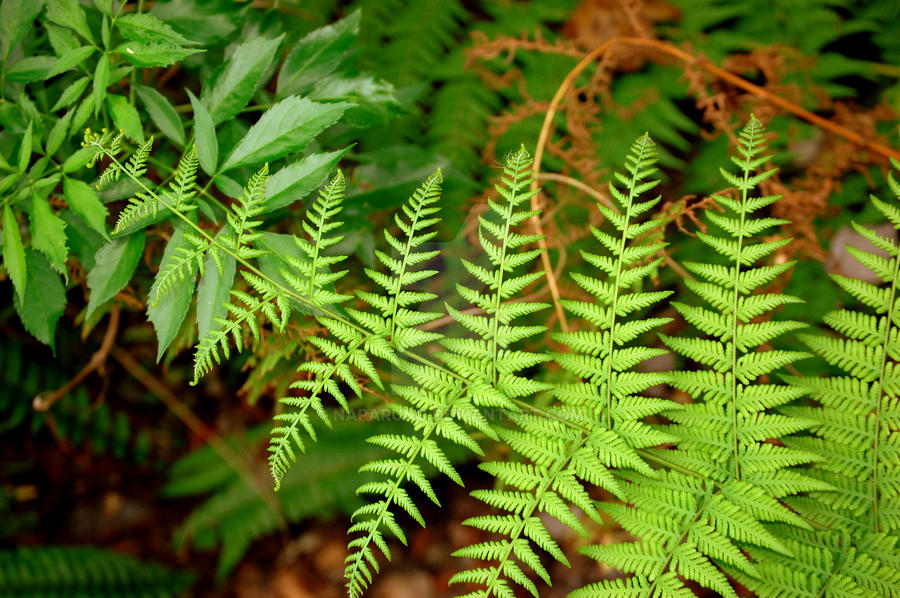  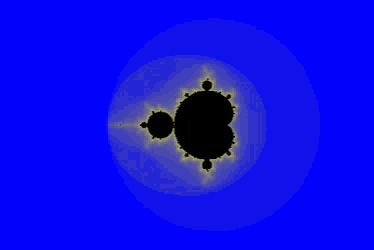

A fractal is a never-ending pattern. It is an infinitely complex patterns that is self-similar across different scales. Fractal patterns are extremely familiar, since nature is full of fractals, like trees, rivers, coastlines, mountains, clouds, seashells, hurricanes, etc. 

A rather beautiful fractal picture can be drawn by plotting the points $\left(x_k ,y_k \right)$ generated by the following difference equations:


$$x_{k+1} =y_k \left(1+\sin \left(0\ldotp 7x_k \right)\right)-1\ldotp 2\sqrt{|x_k |}$$



$$y_{k+1} =0\ldotp 21-x_k$$


starting with $x_0 =y_0 =0$. The following program draws the picture:

NumPoints = 1e5;
[X, Y] = deal(zeros(1, NumPoints));
for k = 1 : NumPoints - 1
    Y(k+1) = 0.21 - X(k);
    X(k+1)= Y(k)*(1 + sin(0.7*X(k))) - 1.2*sqrt(abs(X(k)));
end
plot(X, Y, 'y.', MarkerSize = 0.01);
title('Abstract fractal pattern');
Axes = gca;
Axes.Color = 'blue';

## Advanced Graphics

### 3-D Line Plot

The function `plot3` is the 3-D version of `plot`. The script:

t = 0 : pi/50 : 10*pi;
x = exp(-0.02*t).* sin(t);
y = exp(-0.02*t).*cos(t);
z = t;
plot3(x, y, z);
xlabel('X'); ylabel('Y'); zlabel('Z');

produce the inwardly spiraling helix.

### 3-D Scatter Plot

The following `scatter3 `function call displays circles at the locations specified by `X`, `Y`, and `Z`:

[X, Y, Z] = sphere(16);
x = [0.5*X(:); 0.75*X(:); X(:)];
y = [0.5*Y(:); 0.75*Y(:); Y(:)];
z = [0.5*Z(:); 0.75*Z(:); Z(:)];
scatter3(x, y, z);
xlabel('X'); ylabel('Y'); zlabel('Z');

### Animated Line

The function `comet3` is similar to `plot3` except that it draws with a moving ‘comet head’. Here `comet3` is used to animate the helix:

comet3(x, y, z);
xlabel('X'); ylabel('Y'); zlabel('Z');

### Physics Pinpoint 🔎: Orbit of Halley’s Comet

The equation of an ellipse in polar co-ordinates is given by: $r=a\left(1-e^2 \right)/\left(1-e\;\cos \;\theta \right)$, where $a$ is the semi-major axis and $e$ is the eccentricity, if one focus is at the origin, and the semi-major axis lies on the *x*-axis.

Halley’s Comet, which visited us in 1985, moves in an elliptical orbit about the Sun (at one focus) with a semi-major axis of 17.9 A.U. (A.U. stands for Astronomical Unit, which is the mean distance of the Earth from the Sun). The eccentricity of the orbit is 0.967276. Write a program which draws the orbit of Halley’s Comet and the Earth (assume the Earth is circular, given by $r^2 =x^2 +y^2$).

xSun = 0; ySun = 0;
plot(xSun, ySun, '+');
axis([-5, 37, -5, 37]);
axis('square');
xlabel('x (A.U.)'); ylabel('y (A.U.)');
title('Earth''s and Halley''s comet''s orbits around the Sun');
hold on

Thetas = linspace(0, 2*pi, 300);
rEarth = 1;
xEarth = rEarth * cos(Thetas);
yEarth = rEarth * sin(Thetas);
comet(xEarth, yEarth);

eHalley = 0.967276;
aHalley = 17.9;
rHalley = (aHalley * (1 - eHalley ^ 2)) ./ (1 - eHalley * cos(Thetas));
xHalley = rHalley .* cos(Thetas);
yHalley = rHalley .* sin(Thetas);
comet(xHalley, yHalley);
hold off

legend('Sun', 'Earth', 'Halley''s comet');

### Surface Plot

The `surf` function creates a three-dimensional surface plot, which is a three-dimensional surface that has solid edge colors and solid face colors. The function plots the values in matrix `Z` as heights above a grid in the *x*-*y* plane defined by `X` and `Y`. The color of the surface varies according to the heights specified by `Z`.

The following creates a semitransparent surface by specifying the `FaceAlpha` name-value pair with `0.5` as the value:

[X, Y] = meshgrid(-5 : .5 : 5);
Z = Y .* sin(X) - X .* cos(Y);
SurfPlot = surf(X, Y, Z, FaceAlpha = 0.5);
xlabel('X'); ylabel('Y'); zlabel('Z');

Notice that the surface object is assigned to the variable `SurfPlot` to allow further modifications, for example:

SurfPlot.EdgeColor = 'none';  

### Physics Pinpoint 🔎: Electric Potential Field

The function `quiver` draws little arrows to indicate a gradient or other vector field.

As an example, consider an electric potential field, which is a scalar field, of two variables $V=x^2 +y$. The gradient of $V$ is defined as the vector field:


$$\nabla V=\frac{\partial V}{\partial x}{\hat{a} }_x +\frac{\partial V}{\partial y}{\hat{a} }_y =2x{\hat{a} }_x +{\hat{a} }_y$$


The following code draw arrows indicating the direction of $\nabla V$ at points in the *x*-*y* plane:

[x, y] = meshgrid(-2 : 0.2 : 2, -2 : 0.2 : 2);
V = x.^2 + y;
dx = 2*x;
dy = ones(size(dx)); % dy is same size as dx but all 1's
contour(x, y, V);
hold on
quiver(x, y, dx, dy);
hold off
xlabel('x'); ylabel('y');
legend('V', '∇V');
title('Electric potential field');

## Working with Graphics

You can interactively explore and edit plotted data to improve the visual display of the data or reveal additional information about the data. The interactions available depend on the contents of the axes, but typically include zooming, panning, rotating, data tips, data brushing, and restoring the original view.

Some types of interactions are available through the axes toolbar. The toolbar appears at the top-right corner of the axes when you hover over the chart area.

### **Interactive Exploration**

**Zooming, panning, and rotating** the axes let you explore different views of your data. By default, you can scroll or pinch to zoom in and out of the view of the axes. Also, you can drag to pan (2-D view) or drag to rotate (3-D view). You can enable more interactions by clicking the zoom in  , zoom out  , pan  , and rotate   buttons in the axes toolbar.

**Data tips** appear temporarily as you hover over the data points in your chart. To display persistent (pinned) data tips, click one or more data points. Alternatively, select the data tips button   in the axes toolbar and then click a data point.

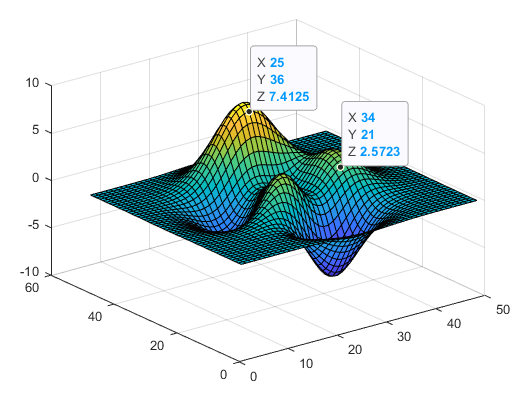

**Data brushing** can be used to select, remove, or replace individual data values. To brush data, select the data brushing button   from the axes toolbar. Click a data point to highlight it or drag a rectangle to highlight all the data points within the rectangle. 

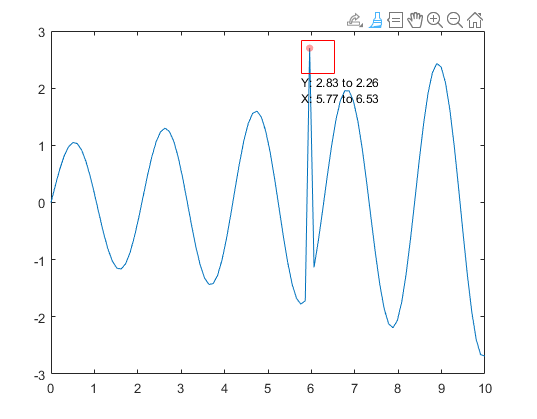

### Interactive Customization

Interactive customization can be performed by using the Property Inspector. When you open the Property Inspector and select a plot, the inspector displays a list of properties that you can edit. To open the inspector, use the `inspect` function or click the Property Inspector button   on the figure toolbar.